## **ЗАДАНИЕ №4.  Приближенное вычисление определенных интегралов**

                    

**4.1. **Вычислить и вывести на печать значения определенного интеграла заданной функции *f*(*x*) при заданных пределах [a; b] двумя методами: методом трапеций (**trapz**) и методом Симпсона (**integral****). **В параметрах команды задать абсолютную точность вычисления интеграла `'AbsTol', `равной значению, заданному в правой колонке таблицы. По умолчанию, в Матлабе относительная точность `'RelTol'`равна `1e-6` . Абсолютная точность  вычисления интеграла по умолчанию,` 'AbsTol'=`  `1e-10`.

**4.2.** Построить  график (**area**) подынтегральной функции. Найти величину всей окрашенной площади, учитывая, что для площади, расположенной ниже оси x, знак интеграла будет отрицательным, и функцию надо подставлять по абсолютной величине.  Сравнить полученный результат с ем, который найден в пункте 4.1.  

clear;
clc;
fun = @(x) sin(1./x).*x.^4;
xmin = 1;
xmax = 2.5;
x = 1:0.1:2.5;
a = trapz(x, fun(x));
b = integral(fun, xmin, xmax, 'AbsTol', 5e-4);
fprintf('Результат интегрирования трапециями: %f \n', a);

Результат интегрирования трапециями: 9.098808 


fprintf('Результат численного интегрирования: %f \n', b);

Результат численного интегрирования: 9.085678 


fprintf('Величина ошибки: %f \n', a - b);

Величина ошибки: 0.013130 


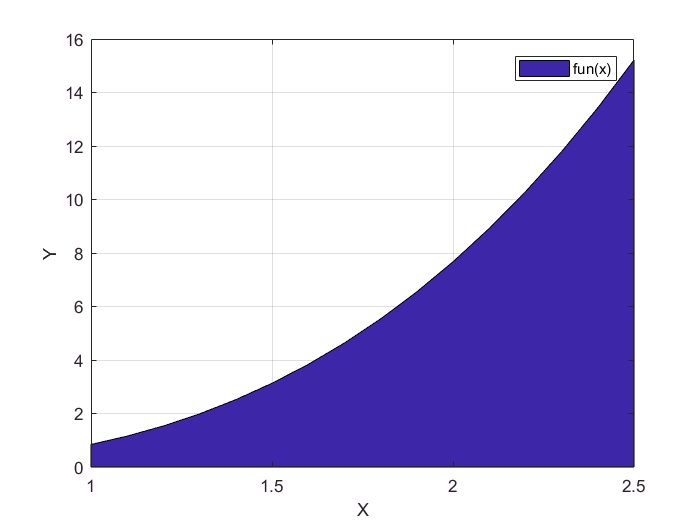

figure('Name', 'Area', 'NumberTitle', 'off');
area(x, fun(x));
xlabel('X');
ylabel('Y');
legend('fun(x)');
grid on;

**4.3.** Построить с помощью команды  meshz(X,Y,Z) график функции (табл.4.2)  из задания 3_4  «Оптимизация». На этом же рисунке, используя команду hold on, построить более широкую «нулевую плоскость» (для большего диапазона изменения аргументов surf(X1,Y1,Z1-Z1)). Если эта плоскость служит основанием заштрихованной трехмерной фигуры, то при помощи команды **integral2**, найти ее объем. Если «нулевая плоскость» пересекает фигуру или не соприкасается с ней, то «сдвинуть» фигуру, изменив функцию Z на такую величину, чтобы «нулевая плоскость» стала ее основанием. Только после этого применить команду  **integral2.**  

Результаты вычислений интегралов вывести в виде таблицы.

clear;
clc;
fun1 = @(x) log(1 + x(1)^2 + x(2)^2)^2 + (x(1) - x(2) - 1)^2;
[xmin, fmin] = fminsearch(fun1, [2; 2]);
fmin = [fmin; fmin];
t = table;
t.Xmin = xmin;
t.Ymin = fmin;
t

t = 2×2 table
      Xmin       Ymin 
    ________    ______

      0.4107    0.1164
    -0.41074    0.1164


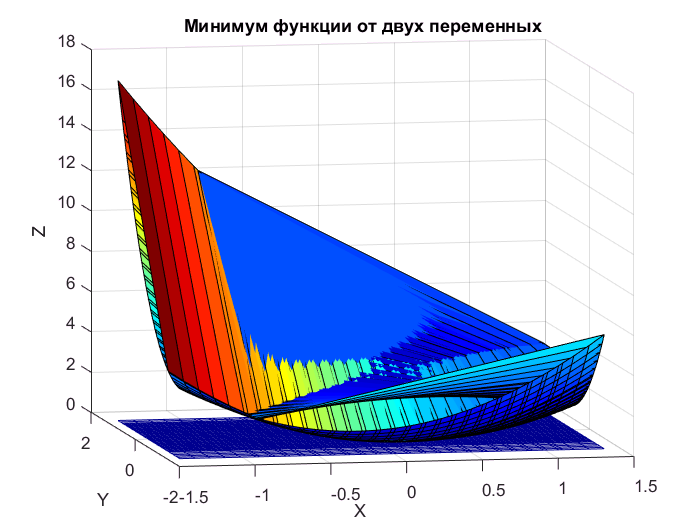

fun = @(x, y) log(1 + x.^2 + y.^2).^2 + (x - y - 1).^2 - fmin(1);
[X,Y] = meshgrid ([xmin(2)-1:0.1:xmin(1)+1, fmin(1)-1:0.1:fmin(1)+1]);
Z = fun(X, Y);
figure('Name', 'fminsearch', 'NumberTitle', 'off');
hold on;
grid on;
meshz(X, Y, Z-Z);
surf(X, Y, Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
colormap('jet');
title('Минимум функции от двух переменных');
view([-11.0 8.7])

a = integral2(fun, xmin(2)-1, xmin(1)+1, fmin(1)-1, fmin(1)+1);
fprintf('Результат численного интегрирования: %f \n', a);

Результат численного интегрирования: 14.970574 
